# Single-Link Planar Robot Manipulator with Distributed Mass

## Clear all data

clc;
clear all;
close all;
clf; %Clear all figures

## Basic Definition

bar_mass = [1]; % mass of bar in kg
bar_length = [1]; %Length of bar in m
center_of_mass  = [0.45];
moment_of_inertia = [0.084];
initial_parameters = [30;0]; % Initial degree (thetha, thetha_dot) parameters of bar
initial_parameters = [deg2rad(initial_parameters(1,1));deg2rad(initial_parameters(2,1))]; % Initial degree (thetha, thetha_dot) parameters of bar
applied_torque = [2]; % Applied torque to the bar (T) 
% where T is applied wrt to +ve x axis
gravitational_acceleration = 9.8; %m/s2
graph_time = 10; % Time frame for plotting

## Symbolic Definition

syms m g h v I w l r x(t) y(t) theta(t) g T 'real' % Creating Symbolic Variables

## Define Generalised Coordinates

q = sym('q',[1,1]);
q(1) = theta;
q

$$q = \theta \left(t\right)$$

dq(1) = diff(q,t)

$$dq = \frac{\partial }{\partial t}\theta \left(t\right)$$

## Defining Generalised Inputs

u = sym('u',[1,1]);
u(1) = T;
u

$$u = T$$

## Derive Lagrangian Function

PE = m*g*h

$$PE = g\,h\,m$$

PE = subs(PE,h,r*sin(theta))

$$PE = g\,m\,r\,\sin\left(\theta \left(t\right)\right)$$

KE = (m*(v^2)/2) + (I*(w^2)/2)

$$KE = \frac{\text{I}\,w^{2}}{2}+\frac{m\,v^{2}}{2}$$

KE = subs(KE,[v],[sqrt(diff(x,t)^2 + diff(y,t)^2)])

$$KE = \frac{m\,\left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}\right)}{2}+\frac{\text{I}\,w^{2}}{2}$$

KE = subs(KE,[x,y,w],[r*cos(theta),r*sin(theta),diff(theta,t)])

$$KE = \frac{m\,\left(r^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+r^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)}{2}+\frac{\text{I}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

LE = KE - PE;
LE = simplify(LE)

$$LE = -\sin\left(\theta \left(t\right)\right)\,g\,m\,r+\frac{\text{I}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m\,r^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

## Derive Euler Lagrangian Equations

dLE_dq = jacobian(LE,q);
dLE_ddq = jacobian(KE,dq);
d_dLE_dtDdq = diff(dLE_ddq,t);
EU_eq1 = d_dLE_dtDdq - dLE_dq(1,1) - u(1) == 0;
EU_eq1 = simplify(EU_eq1);
syms phi phi_dot phi_ddot 'real'
EU_eq1 = subs(EU_eq1,[theta, diff(theta,t), diff(theta,t,2)],[phi, phi_dot, phi_ddot])

$$EU\_eq1 = T=\text{I}\,\ddot{\varphi }+m\,\ddot{\varphi }\,r^{2}+g\,m\,r\,\cos\left(\varphi \right)$$

## Symbolic Solution to EL Equation

[phi_ddot] = solve(EU_eq1,phi_ddot)

$$phi\_ddot = \frac{T-g\,m\,r\,\cos\left(\varphi \right)}{\text{I}+m\,r^{2}}$$

## Defining State Space Matrix

%x = sym('X',[2,1]); %Create a 2X1 State Space Matrix Vector
%x(1) = phi;
%x(2) = phi_dot;
%x

## Calculating Differential Equation to get thetha

fun_dX = @(t,x)fun_dX(t,x,applied_torque(1,1), bar_mass,gravitational_acceleration, bar_length,center_of_mass(1,1),moment_of_inertia(1,1));% Convert the symbolic matrix to double matrix
tspan =[0 graph_time];
[t,state_space_matrix] = ode45(fun_dX,tspan,initial_parameters);
r_size = size(t);
position = zeros(r_size(1,1),2);
for i = 1:r_size(1,1)
    position(i,1) = bar_length*cos(state_space_matrix(i,1));
    position(i,2) = bar_length*sin(state_space_matrix(i,1));
end

## Animation

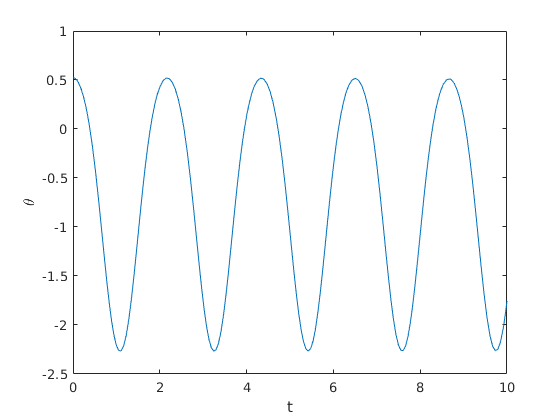

xAxisArrayXCoordinates = [-2 2];
xAxisArrayYCoordinates = [0 0];
yAxisArrayXCoordinates = [0 0];
yAxisArrayYCoordinates = [-2 2];
th = 0:pi/50:2*pi;
xunit = bar_length * cos(th);
yunit = bar_length * sin(th);
plot(t,state_space_matrix(:,1))
xlabel('t')
ylabel('\theta')

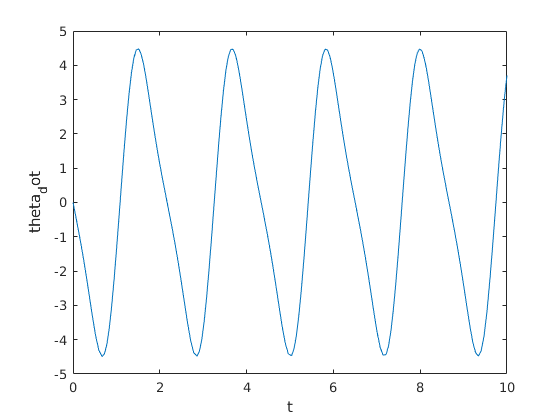

plot(t,state_space_matrix(:,2))
xlabel('t')
ylabel('theta_dot')

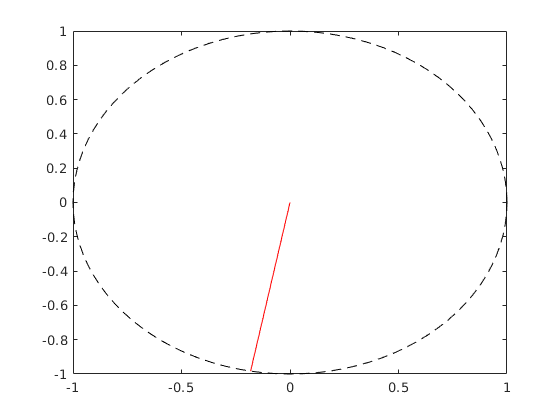


for i = 1:1:r_size(1,1)
    link1XCoordinates = [0 position(i,1)];
    link1YCoordinates = [0 position(i,2)];
    %Plotting Graph
    %plot(xAxisArrayXCoordinates, xAxisArrayYCoordinates,'black', yAxisArrayXCoordinates, yAxisArrayYCoordinates, 'black');% Draw rectangular axes
    plot(xunit, yunit,'k','LineStyle','--'); % Draw Circular Axes
    hold on;
    plot(link1XCoordinates, link1YCoordinates, 'red');
    pause(0.1); % pause to see realtime animation. Given in seconds
    hold off;
end